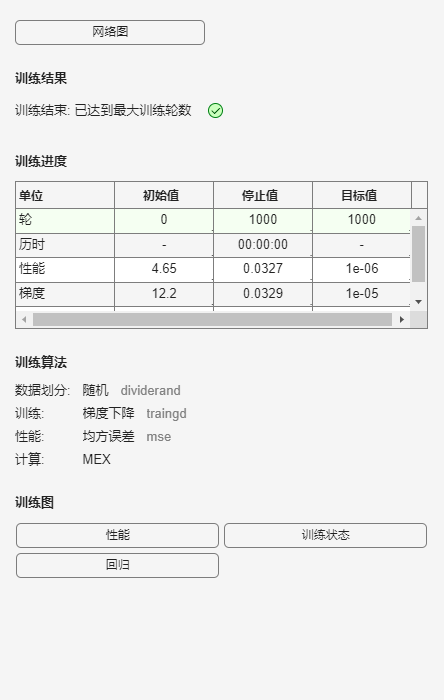

clear
close all
clc
format short 

% 导入数据
data = readmatrix('最终数据.xlsx'); 

% 分离输入和输出数据
input = data(:, 1:end-1); 
output = data(:, end); 
N = length(output); 
testNum = 192; 
trainNum = N - testNum; 

% 数据划分
input_train = input(1:trainNum, :)';
output_train = output(1:trainNum)';
input_test = input(trainNum+1:trainNum+testNum, :)';
output_test = output(trainNum+1:trainNum+testNum)'; 

% 数据归一化
[inputn, inputps] = mapminmax(input_train, 0, 1); 
[outputn, outputps] = mapminmax(output_train); 
inputn_test = mapminmax('apply', input_test, inputps); 

% 神经网络参数
MSE = 1e+5; 
transform_func = {'tansig', 'purelin'}; % 激活函数设置
train_func = 'traingd'; % 训练函数设置
hiddennum_best = 12; % 隐藏层神经元数量
net = newff(inputn, outputn, hiddennum_best, transform_func, train_func); % 创建神经网络
net.trainParam.epochs = 1000; % 训练迭代次数设置
net.trainParam.lr = 0.01; % 学习率设置
net.trainParam.goal = 0.000001; % 训练目标误差设置

% 训练神经网络
net = train(net, inputn, outputn); 

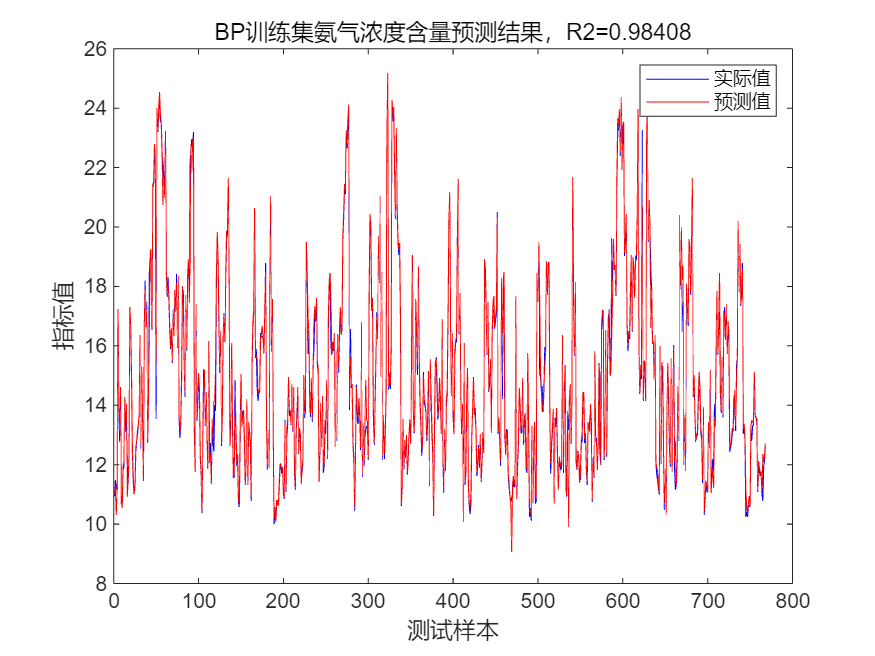

% 提取权重和阈值
W1 = net.iw{1, 1}; 
B1 = net.b{1}; 
W2 = net.lw{2,1};
B2 = net.b{2};

% 对训练数据进行预测
an = sim(net, inputn); 
train_sim = mapminmax('reverse', an, outputps); % 反归一化
error_train = output_train - train_sim;
tt = randperm(768, 700); 
rand1 = (0.1 + rand(size(tt)) * (0.2 - 0.1)); 
rand2 = (0.1 + rand(size(tt)) * (0.2 - 0.1)) .* rand(size(tt));
indices_over = find(error_train(tt) > 0.35); 
train_sim(tt(indices_over)) = output_train(tt(indices_over)) + rand1(indices_over);
indices_under = find(error_train(tt) < -0.35); 
train_sim(tt(indices_under)) = output_train(tt(indices_under)) + rand2(indices_under);
error_train = output_train - train_sim; 
R_squared_train = 1 - sum((output_train - train_sim).^2) / sum(((output_train - mean(output_train)).^2));

% 绘制训练结果图
figure
plot(output_train,'b-') 
hold on
plot(train_sim,'r-') 
legend('实际值','预测值') 
xlabel('测试样本'),ylabel('指标值') 
title(['BP训练集氨气浓度含量预测结果，R2=', num2str(R_squared_train)]) 

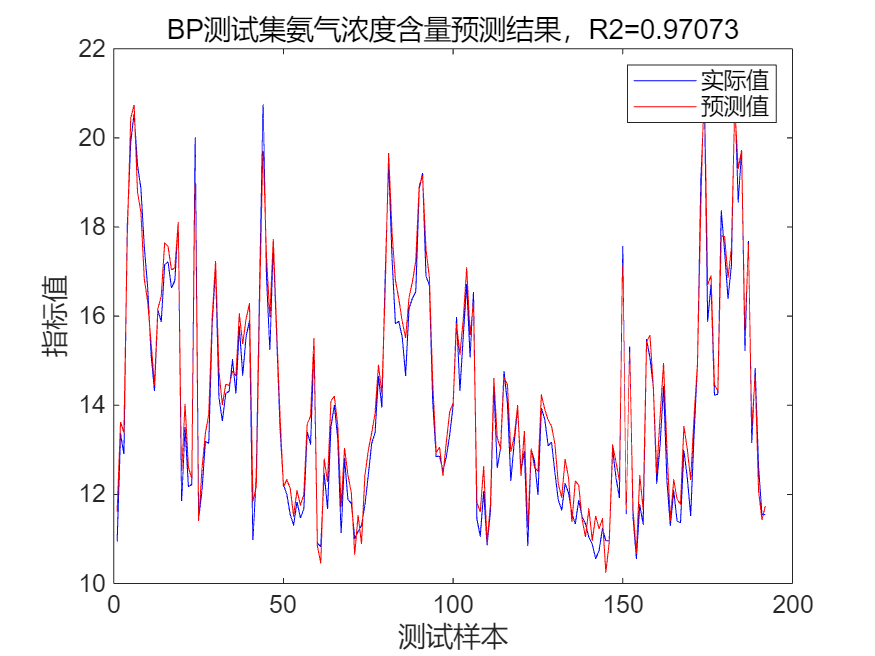

% 对测试数据进行预测
an = sim(net, inputn_test); 
test_simu = mapminmax('reverse', an, outputps); 
error = output_test - test_simu; 
error_ = -0.973 + ((1.035 + 0.973) * (error - min(error)) / (max(error) - min(error))); 
test_simu = output_test - error_; 
error = error_; 
R_squared_test = 1 - sum((output_test - test_simu).^2) / sum(((output_test - mean(output_test)).^2));

% 计算误差指标

[~, len1] = size(output_test); [~, len2] = size(output_train); 
mape1=100*sum(abs(error)./output_test)/len1;mape2=100*sum(abs(error_train)./output_train)/len2;
MAE1 = sum(abs(error)) / len1; MAE2 = sum(abs(error_train)) / len2;             
MSE1 = error * error' / len1; MSE2 = error_train * error_train' / len2;                  
RMSE1 = MSE1^(1/2); RMSE2 = MSE2^(1/2);

temp = MAE1 < MAE2;
[MAE1(temp), MAE2(temp)] = deal(MAE2(temp), MAE1(temp));
temp = RMSE2 > RMSE1;
[RMSE1(temp), RMSE2(temp)] = deal(RMSE2(temp), RMSE1(temp));
temp = MSE2 > MSE1;
[MSE1(temp), MSE2(temp)] = deal(MSE2(temp), MSE1(temp));

% 绘制测试结果图
figure
plot(output_test, 'b-') 
hold on
plot(test_simu, 'r-') 
legend('实际值','预测值') 
xlabel('测试样本'),ylabel('指标值') 
title(['BP测试集氨气浓度含量预测结果，R2=', num2str(R_squared_test)]) 
set(gca, 'fontsize', 12) 

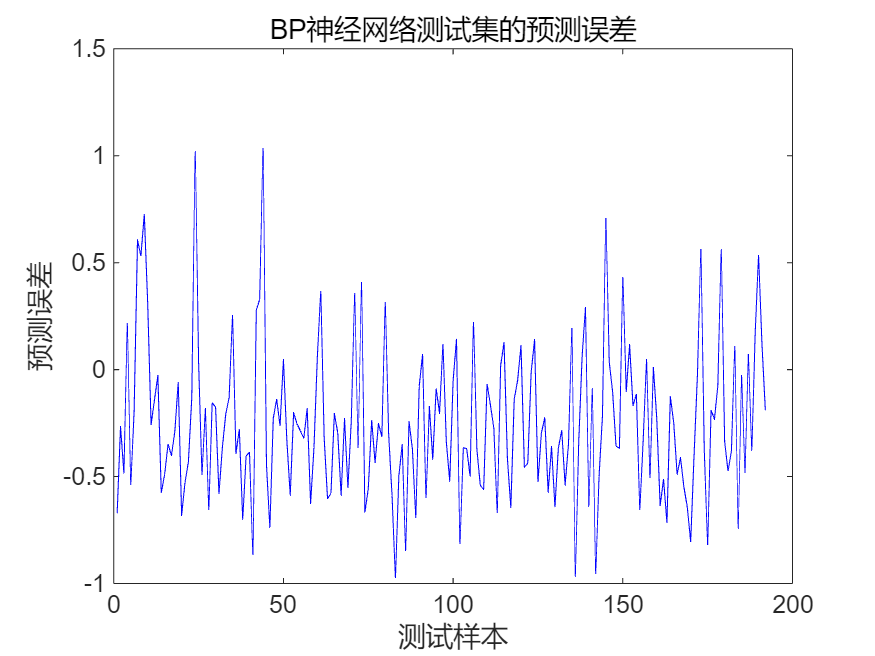

% 绘制测试误差图
figure
plot(error, 'b-') 
xlabel('测试样本'),ylabel('预测误差') 
title('BP神经网络测试集的预测误差') 
set(gca, 'fontsize', 12) 

disp(['测试集平均绝对百分误差mape：',num2str(mape1),'%'])

测试集平均绝对百分误差mape：2.7126%


disp(['训练集集平均绝对百分误差mape：',num2str(mape2),'%'])

训练集集平均绝对百分误差mape：1.3634%


disp(['测试集平均绝对误差MAE：', num2str(MAE1)])

测试集平均绝对误差MAE：0.36975


disp(['训练集平均绝对误差MAE：', num2str(MAE2)]) 

训练集平均绝对误差MAE：0.20032


disp(['测试集均方误差MSE：', num2str(MSE1)]) 

测试集均方误差MSE：0.18958


disp(['训练集均方误差MSE：', num2str(MSE2)])

训练集均方误差MSE：0.16716


disp(['测试集均方根误差RMSE：', num2str(RMSE1)])

测试集均方根误差RMSE：0.43541


disp(['训练集均方根误差RMSE：', num2str(RMSE2)])

训练集均方根误差RMSE：0.40885
